cache = load("cache_.mat");

mul_target_spike = cache.cache.mul_target_spike;
mul_target_trcnt = cache.cache.mul_target_trcnt;
isi_targets = cache.cache.isi_targets;

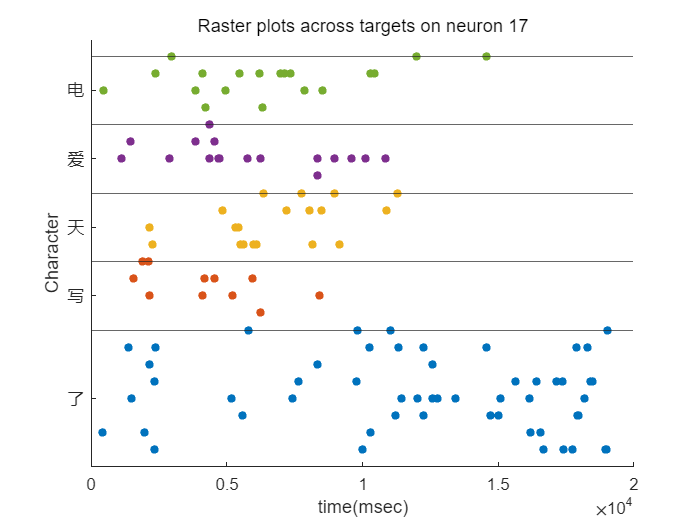

target_cnt = length(isi_targets);
target_trial_tlen = size(mul_target_spike, 2);
neuron_id_plt = 17;
tid = 0;    % target分段
for i = 1: target_cnt
    scatter_x = [];
    scatter_y = [];
    tg_trcnt = mul_target_trcnt(i);
    if i>1
        tid = tid+mul_target_trcnt(i-1);
    end
    for k = tid+1: tid+mul_target_trcnt(i)
        for j = 1: target_trial_tlen
            if mul_target_spike(k, j) > 0
                scatter_x = [scatter_x, j];
                scatter_y = [scatter_y, k];
            end
        end
    end
    % 完成了一个target的数据查找
    scatter(scatter_x, scatter_y, 25, 'filled');
    yline(k);
    if i < target_cnt
        hold on;
    end
end
hold off;
% title yticks xticks
title("Raster plots across targets on neuron "+string(neuron_id_plt));
cs_mtt = cumsum(mul_target_trcnt); % [4 8 16 20 24 28]
ytick_arr = zeros(1, length(mul_target_trcnt));    % [0 0 0 0 0 0]
ytick_arr(1) = cs_mtt(1)/2; % [2 0 0 0 0 0]
for i =2: length(ytick_arr)
    ytick_arr(i) = (cs_mtt(i)+cs_mtt(i-1))/2;
end
yticks(ytick_arr);
yticklabels(isi_targets);
ylabel("Character");
xlabel("time(msec)");

## Inter spike interval distribution

什么是ISI？ISI刻画了神经元发放时序特征的一个侧面，具体的，它显示了神经元两次发放的时间间隔的分布

% 依旧从 trial_bin_spike 计算
load("../../../../data/backup/Patient.00001.mat_spike_data.mat");
trial_bin_spike = spike_data.trial_bin_spike;
trial_cn = size(trial_bin_spike, 1);
time_len = size(trial_bin_spike, 2);
unit_cnt = size(trial_bin_spike, 3);

% 选取 neuron id
neuron_id_plt = 18;

% 选取该神经元的发放数据
neuron_spike = trial_bin_spike(:, :, neuron_id_plt);
neuron_spike = reshape(neuron_spike, [trial_cn, time_len]);

% 获取间隔
neuron_interval = [];
for i=1:trial_cn
    firing_tick = find(neuron_spike(i, :));
    neuron_interval = [neuron_interval, firing_tick(1)];
    for j = 2:length(firing_tick)
        neuron_interval = [neuron_interval, (firing_tick(j)-firing_tick(j-1))];
    end
end

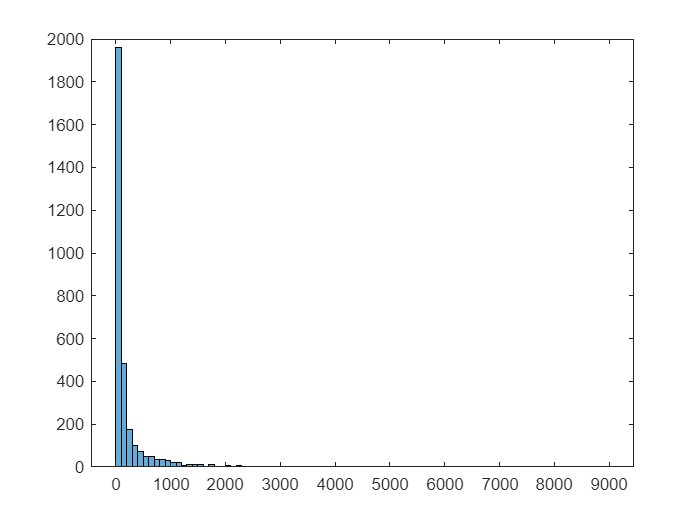

% 画直方图
histogram(neuron_interval);